clear variables; close all; clc;

## DKE Introduction to Bioinformatics 2022

# Phylogenetic trees

Continuing with Corona viruses, we're going to make a phylogenetic tree with data from different corona viruses, to show how they are related.

The site [https://nextstrain.org/](https://nextstrain.org/ncov/global) has a lot of genetic data on different virus datasets, including corona viruses.  

We'll start with the file of the metadata for a selection of samples from different beta-Corona Viruses.  **The file is provided with this practical**, but was originally obtained from this page [https://nextstrain.org/groups/blab/sars-like-cov](https://nextstrain.org/groups/blab/sars-like-cov) (I clicked download data at the bottom of the page and then selected the 'All Metadata' option) to get a tab separated file.  I then opened it in excel, deleted the samples without GENBANK accession numbers (this took a bit of trial and error, as some records had been removed from genbank) and also reduced the number of samples, so there was only one example of each group and resaved it as a csv to load into Matlab.  Which is the file I have provided for you.

- Read this file into Matlab and take a look at it. 

CoronaViruses = readtable("CoronaVirusesMetadataReduced.csv","VariableNamingRule","preserve")

CoronaViruses = 7×9 table
           Strain               Clade            country         host       url       virus type             Author          Accession                Labels          
    ____________________    ______________    _____________    _________    ___    _________________    ________________    ____________    __________________________

    {'bat_SL_CoVZXC21' }    {0×0 char    }    {'China'    }    {'Bat'  }    NaN    {'SARS-like CoV'}    {'Hu et al A'  }    {'MG772934'}    {'ChinaBatSARS-like CoV' }
    {'Wuhan/WIV05/2019'}    {'SARS-CoV-2'}    {'China'    }    {'Human'}    NaN    {'SARS-CoV-2'   }    {'Zhou et al'  }    {'MN996529'}    {'ChinaHumanSARS-CoV-2'  }

[rows,columns] = size(CoronaViruses);

      The accession column of this file gives the genbank accession numbers for each of the sequences. 

    2. Make a loop to download all the sequences and store them. 

sequences = cell(rows,1);
names = cell(rows,1);
for i=1:rows
    access = string(CoronaViruses.Accession(i));
    names{i} = CoronaViruses.Strain(i);
    gen = getgenbank(access);
    sequences{i} = gen.Sequence;
end
data = struct("Name",names,"Sequence",sequences);

        3. Now we are ready to calculate the distances between the sequences.  Use the function **seqpdist** and set **SquareForm **to be true to tell it to output a square matrix with the distances.  (NB. This calculation took over 5 minutes on my computer, so be patient!)

                a) Visualise your distance matrix, what does this tell you about the sequences.

M = seqpdist(sequences,squareform=true)

M =          0    0.1323    0.2068    0.2173    0.2105    0.2096    0.2078
    0.1323         0    0.2257    0.2346    0.2289    0.2268    0.2262
    0.2068    0.2257         0    0.0520    0.0463    0.0443    0.0436
    0.2173    0.2346    0.0520         0    0.0099    0.0132    0.0112
    0.2105    0.2289    0.0463    0.0099         0    0.0086    0.0067
    0.2096    0.2268    0.0443    0.0132    0.0086         0    0.0027
    0.2078    0.2262    0.0436    0.0112    0.0067    0.0027         0


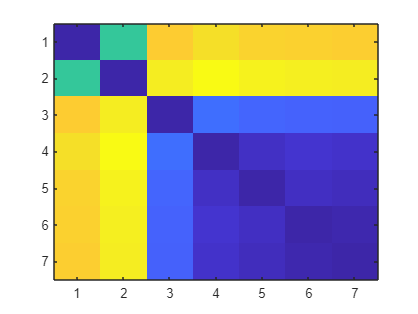

imagesc(M)

    4.  The function **seqlinkage** will build the tree and save it in a variable, and then applying the **plot** function to this variable will plot the tree.  Make sure your leaves are labelled.  What does this tree tell us about the new SARS-CoV2 virus (COVID19)?

str = string(names);
tree1 = seqlinkage(M,'average',str)

    Phylogenetic tree object with 7 leaves (6 branches)


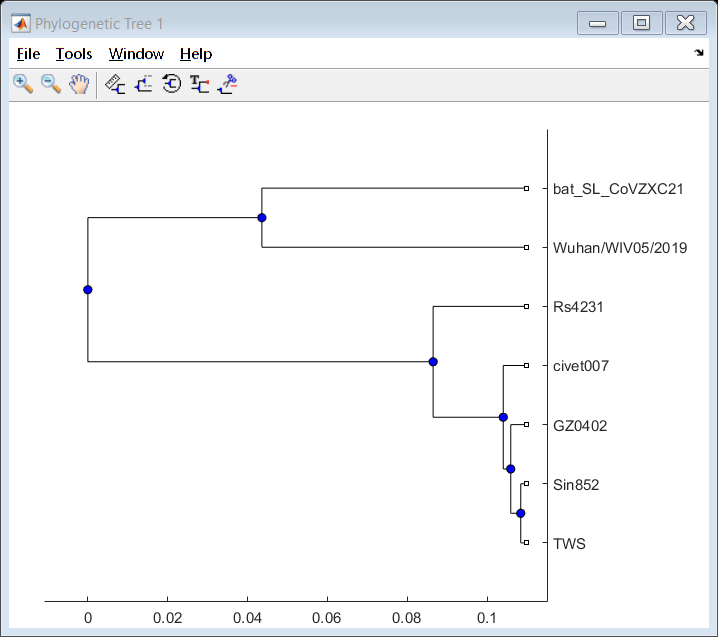

figure; view(tree1)

5. The function **seqneighjoin **will build the tree using neighbour joining.  How does this tree compare with your original tree?  Which method is the most appropriate to use with viral data like this?

tree2 = seqneighjoin(M,'equivar',str)

    Phylogenetic tree object with 7 leaves (6 branches)


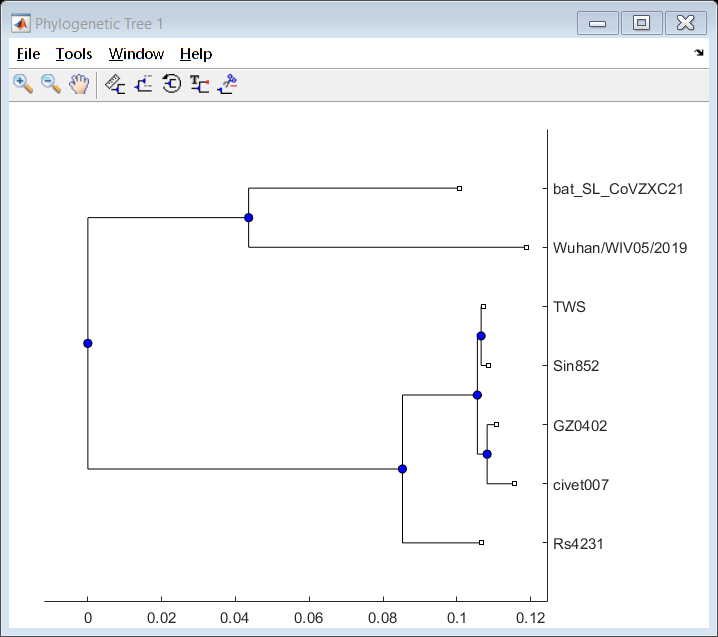

view(tree2)

**Assignment:**

Pick a different subset of data from the nextstrain site, download the metadata file and clean it up (see the process I noted I used at the top of this script), so it can be used to build a tree - you may wish to select only a subset of the data, for computational reasons (especially if the sequences are long).  Upload your metadata file with your assignment.  

State a research question you want to explore using your chosen dataset (and that can be answered by building a phylogenetic tree).  

Then build a phylogenetic tree to answer your research question and draw some conclusions from your investigation.  

NB. If you did this practical last year, I expect a different data subset and a different research question for the practical this year.